# Project

Author: Mahmud Suhaimi Ibrahim

Date: 04/21/2025

clc; clear; close all;

You are told that the design should have a **rated speed of 10,000 RPM**, have a **rated power of 50 kW**, have an **electric frequency under 600 Hz**, have **three phases**, use **surface mounted permanent magnets** on the rotor, and use forced air cooling. You need to determine the number of slots, poles, the winding layout, and various dimensions of the machine.

## Question 1

Propose **a number of slots and poles** that you wish to use in your design which satisfies the** electric frequency** and** symmetry requirements**. Submit this in Canvas as your first deliverable in the form of a ranked list of 3 slot / pole combinations you are interested in. 

### Answer:

First, I want to mention that I am choosing the number of slots and poles for a double-layer slot winding. The number of poles of the machine is related to the number of poles by the following formula:

$f=\frac{P\cdot N}{120}$,

where $f$ is the electrical frequency, $P$ is the number of poles (**NOT **pole pairs), and $N$ is the synchronous speed in RPM.

Rearranging the equation to make $P$ the subject gives us:


$$P=\frac{120\cdot f}{N}$$


But since the frequency has to be less than 600 Hz, the number of poles is bound by this equation:


$$P<\frac{120\cdot f}{N}$$


f = 600; % Frequency in Hertz
N = 10e3; % Speed in RPM

P_max = (120*f)/N;

The maximum number of poles is:

disp(round(P_max))

     7



Considering that I have to have an even number of poles, the options available are 2,4, and 6 poles. 

Some background *(Pyrhönen, J., Jokinen, T., & Hrabovcová, V. (2014). Design of rotating electrical machines (2nd ed.). Wiley.)*:

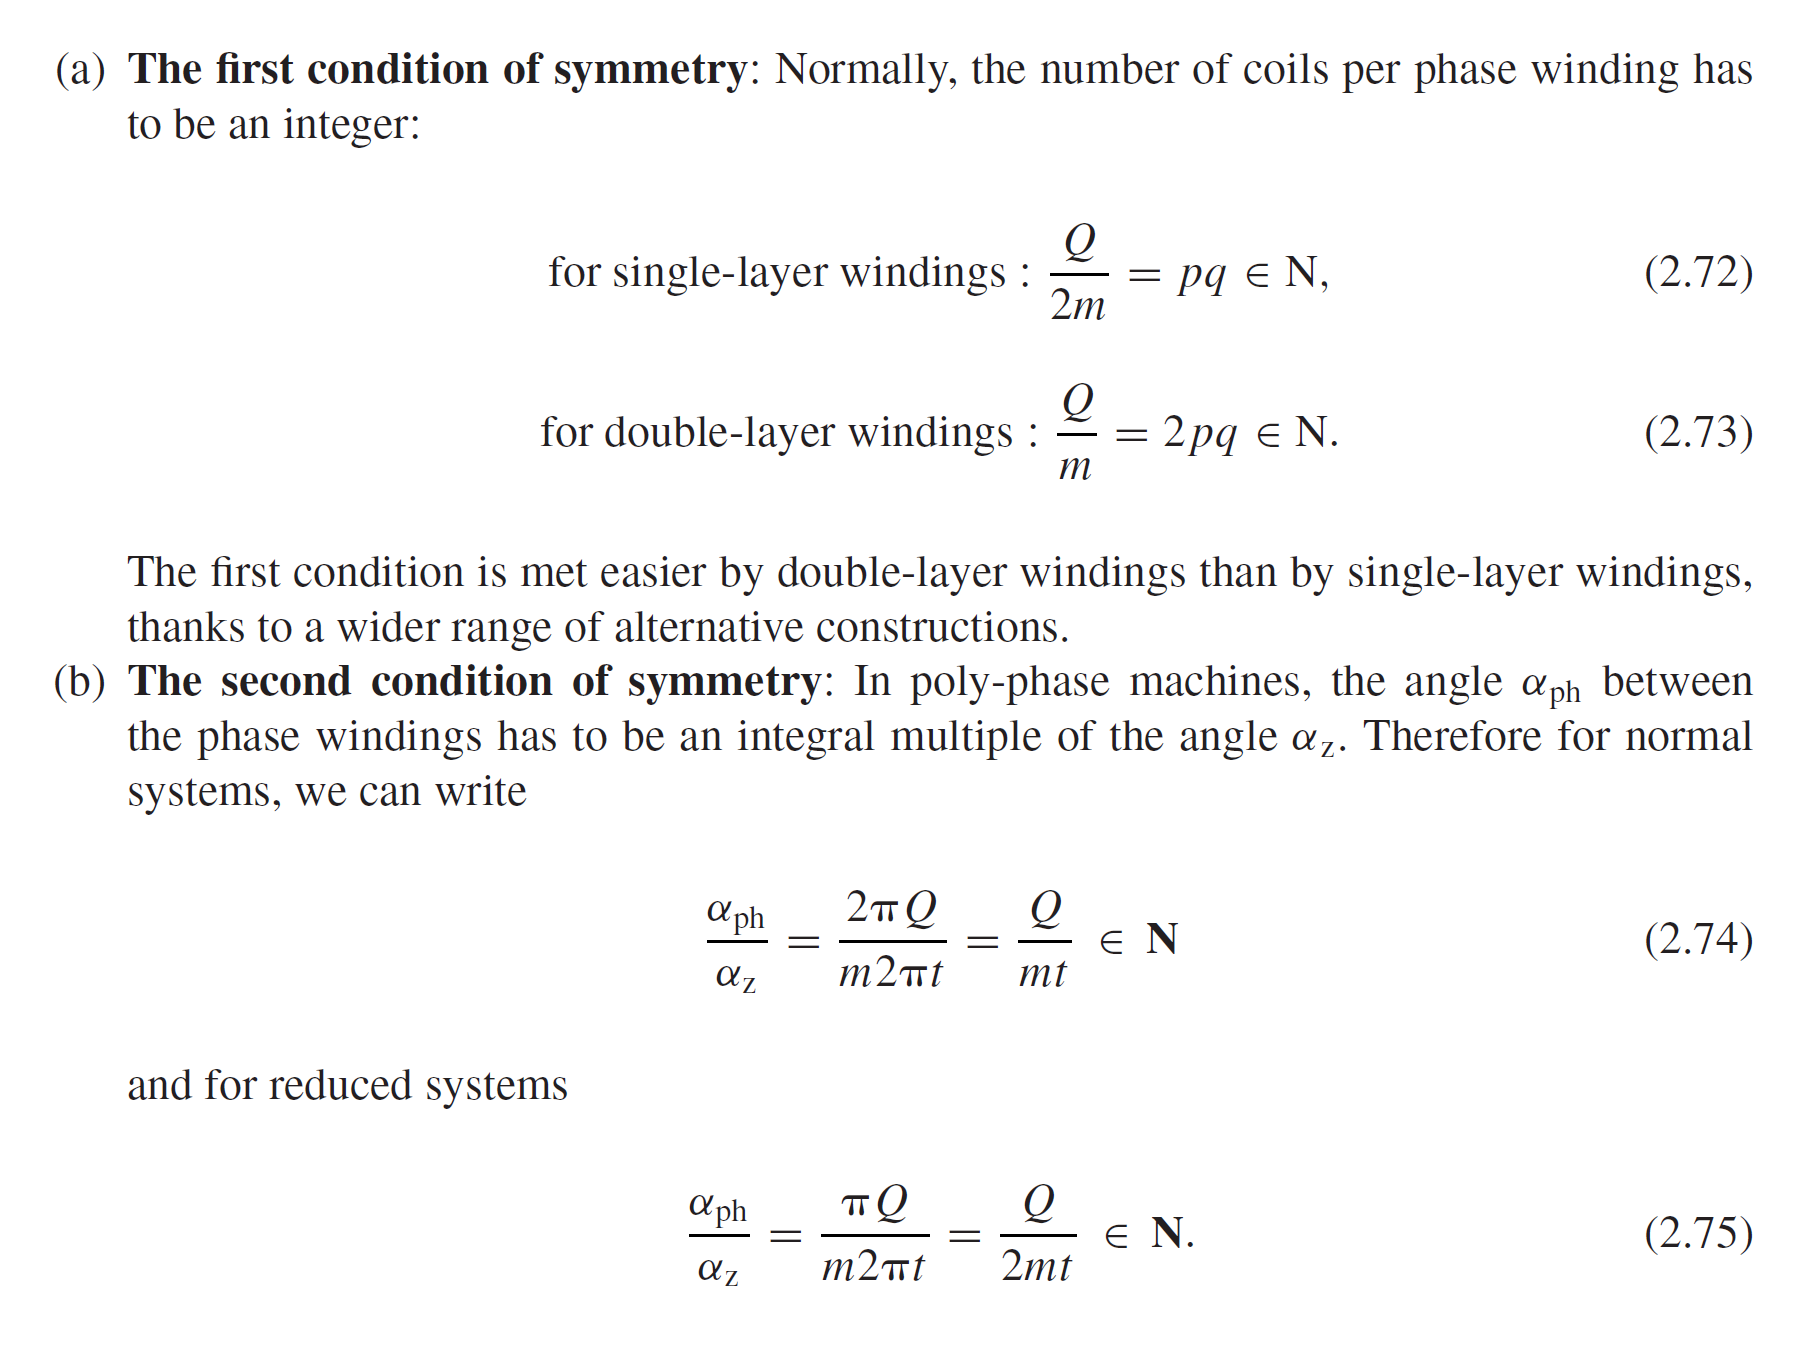

I have to check if my slot-pole combination meets the symmetry conditions for a normal system (3-phase system) with double-layer winding.

### Combination 1 (Rank 3):

$P=2$ or $p=1$; the number of pole pairs.

$m=3$ is given as one of the requirements.

Now I need to make sure that I have a symmetric winding. So I will use the rules for symmetry as constraints.

$\frac{Q}{m}\in N$ and $\frac{Q}{mt}\in N$, where $t=GCD(Q,p)$.

Since$p=1$, the $t$ will also always be 1 in this case. Therefore, the two constraints are the same for this option.


$$\frac{Q}{3}\in N$$


Q must be a multiple of 3 for this machine to have a symmetric winding. 

I will pick $Q=12$ as I am familiar with this slot-pole combination and I know that the magnitude of the winding factor of the first harmonic is equal to 0.966. Refer to lecture 10-3 for the winding factor of this combination.

$q=\frac{Q}{2pm}=\frac{12}{2(1)(3)}=2\in N$, which means this an integer slot winding.

**The combination: **

### 
$$Q=12, P=2$$


### Combination 2 (Rank 2):

$P=4$ or $p=2$, and $m=3$

$Q$ still has to be a multiple of 3.

$t=GCD(Q,2)$, if Q is an odd number, then $t=1$.

I will pick $Q=27$ this time around to reduce torque ripple.

Both symmetry conditions are met!

$q=\frac{Q}{2pm}=\frac{27}{2(2)(3)}=\frac{9}{4}\not\in N$, which means this a fractional slot winding.

**The combination:**

### 
$$Q=27, P=4$$


### Combination 3 (Rank 1):

$P=6$ or $p=3$, and $m=3$

I will pick $Q=36$, which will make $t=GCD(36,3)=3$.

The winding is symmetric as both conditions are met.

After googling a little bit, I found that this is a machine available in the market, so it must have some benefits.

$q=\frac{Q}{2pm}=\frac{36}{2(3)(3)}=2\in N$, which means this an integer slot winding.

**The combination:**

### 
$$Q=36, P=6$$
